## Load Data

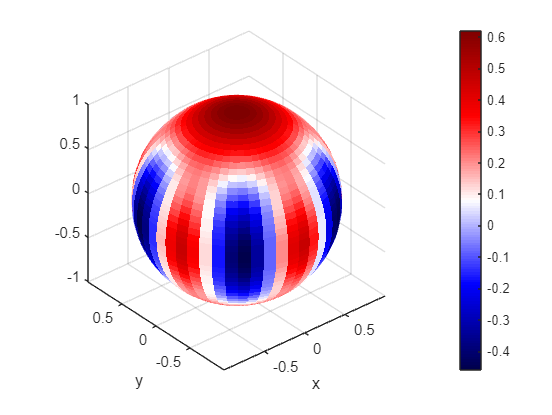

clear all;
load('cat.mat');
wigner_plot_only_fun(a);


load("detect_cat.mat");
wigner_plot_only_fun(wigner_result);

load("initial.mat");
wigner_plot_only_fun(wigner_result);

load("precess_cat.mat");
wigner_plot_only_fun(wigner_result);


function wigner_plot_only_fun(wigner_result)
    [m,n]=size(wigner_result);
    theta_list=[0:pi/(m-1):pi];
    phi_list=[0:2*pi/(n-1):2*pi];
    f1=figure;
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,real(wigner_result));
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    %caxis([-1 1]);
    xlabel('x');
    ylabel('y');
    %view([0 90]);
    %set(f1,"Visible","On");
    %daspect([1 1 1]);
    axis equal;
    set(surf,"LineStyle","none", "FaceColor","texturemap",...
        "FaceLighting","gouraud");
    colorbar;
    cMap=getPyPlot_cMap('seismic');
    colormap(cMap);
end